# Silhouette Plots

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

X = readmatrix("./data/data2.csv");
X = X(:, [1, 2]);
yCat = readmatrix("./data/data2.csv", OutputType="string");
yCat = categorical(yCat(:, 3));
whos X yCat

  Name        Size            Bytes  Class          Attributes

  X         600x2              9600  double                   
  yCat      600x1               818  categorical              



This code clusters the data into 2 groups using `kmeans`.

grp = kmeans(X, 2);

## Task 1

The observations in `X` have been divided into 2 groups using *k*-means clustering.

You can use the [`silhouette`](https://www.mathworks.com/help/stats/silhouette.html) function to measure how close each observation is to other observations in the same cluster.

`silhouette``(``data``,``groups``)`

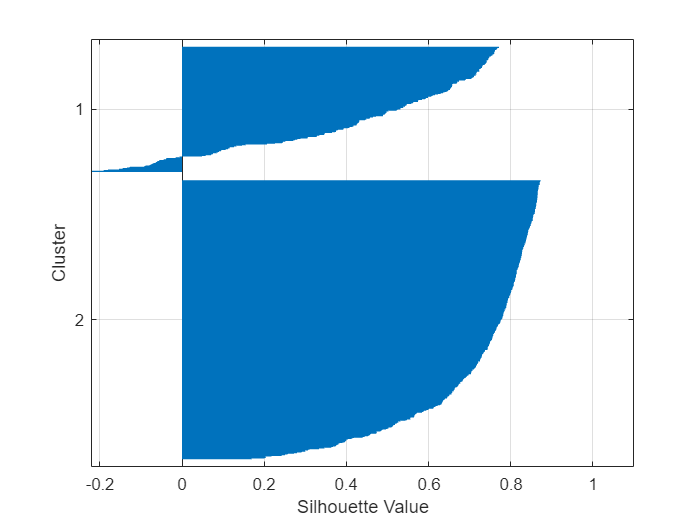

silhouette(X, grp)
grid on

## Task 2

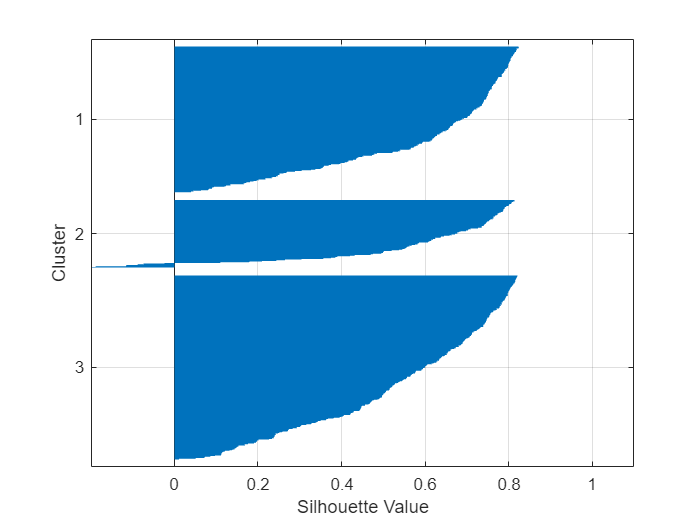

grp3 = kmeans(X, 3);
silhouette(X, grp3)
grid on

## Task 3

If you're not certain about how many groups to use, the [`evalclusters`](https://www.mathworks.com/help/stats/evalclusters.html) function can help you make the decision.

The following command uses the silhouette values with `kmeans` to evaluate the optimal number of clusters.

`eva` `=` `evalclusters``(``data``,``...`

    `"kmeans"``,``"silhouette"``,``...`

    `"KList"``,``vectorOfPositiveIntegers``)`

clustEv = evalclusters(X, "kmeans", "silhouette", "KList", 2:5)

clustEv =   SilhouetteEvaluation with properties:

    NumObservations: 600
         InspectedK: [2 3 4 5]
    CriterionValues: [0.6354 0.5768 0.5139 0.5157]
           OptimalK: 2
